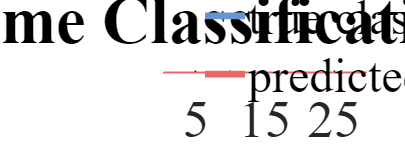

% 데이터 불러오기 (예제에서는 CSV 파일을 사용)
data = readtable('./output/video (76)-YOLOLSTM.csv', 'ReadVariableNames', false);

% 첫 번째 열: frame_idx, 두 번째 열: YOLO_pred, 네 번째 열: YOLO_true
frame_idx = (1:length(data.Var1))'.*0.25;
YOLO_pred = data.Var2;
YOLO_true = data.Var4;

% 치환 함수 정의
replaceLabels = @(x) 2 * (x == 1) + 2 * (x == 0) + 2 * (x == 2) + 0 * (x == 6) + 1 * (x == 4) + 1 * (x == 3) + 1 * (x == 5);

% YOLO_true와 YOLO_pred 값 치환
YOLO_true = arrayfun(replaceLabels, YOLO_true);
YOLO_pred = arrayfun(replaceLabels, YOLO_pred);


% 축 레이블 설정
labels_YOLO = {'LG', 'IC', 'DC'};
y_data = [0 1 2];

% 그래프 그리기
figure('Position', [100, 100, 2700, 1000]);  % 가로로 긴 그래프 설정
hold on;

plot(frame_idx, YOLO_true, Color=[104/255, 149/255, 210/255],LineWidth=5);
plot(frame_idx, YOLO_pred, Color=[238/255, 102/255, 102/255],LineWidth=5);


% 축 레이블 및 제목 설정
set(gca, 'YTick', y_data, 'YTickLabel', labels_YOLO,'FontSize',40,'FontName','Times New Roman');
xlabel('Time (s)');
ylabel('Label');
title('Real-time Classification: YOLO','FontSize',50,'FontWeight','bold');
% 범례 설정 (박스 없애기, 위치 설정)
legend('true class', 'predicted class', 'Box', 'off');
% x 축 레이블 설정
% y 축 설정 (라벨로 설정)

legend("Position", [0.76,0.55,0.3,0.3])


xlim([frame_idx(1,:) frame_idx(end)]);
% y축 범위 설정
ylim([-1 3]);
grid on


% 그리기 종료


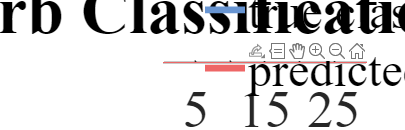


LSTM_pred=data.Var3;
LSTM_true=data.Var4;

% 치환 함수 정의
replaceLabels = @(x) 0 * (x == 2) + 1 * (x == 1) + 2 * (x == 0) ;

% 축 레이블 설정
labels_LSTM = {'LG', 'IC', 'DC' ,' '};
y_data = [0 1 2 3];

% YOLO_true와 YOLO_pred 값 치환
LSTM_true = arrayfun(replaceLabels, LSTM_true);
LSTM_pred = arrayfun(replaceLabels, LSTM_pred);

% 그래프 그리기
figure('Position', [100, 100, 2500, 800]);  % 가로로 긴 그래프 설정
hold on;
plot(frame_idx, LSTM_true, Color=[104/255, 149/255, 210/255],LineWidth=5);
plot(frame_idx, LSTM_pred, Color=[238/255, 102/255, 102/255],LineWidth=5);

% 축 레이블 및 제목 설정
xlabel('Time (s)');
ylabel('Label');
set(gca, 'YTick', y_data, 'YTickLabel', labels_LSTM,'FontSize',40,'FontName','Times New Roman');
title('Real-time Curb Classification: YOLO-LSTM','FontSize',50,'FontWeight','bold');
% 범례 설정 (박스 없애기, 위치 설정)
legend('true class', 'predicted class', 'Box', 'off');
% x 축 레이블 설정
% y 축 설정 (라벨로 설정)
legend("Position", [0.76,0.55,0.3,0.3])


xlim([frame_idx(1,:) frame_idx(end)]);
% y축 범위 설정
ylim([-1 3]);
grid on
% 그리기 종료
hold off;

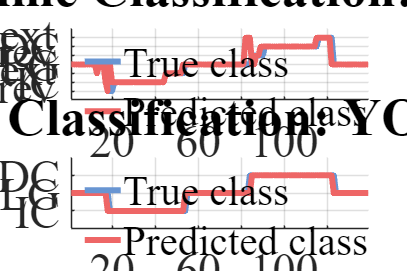

% 데이터 불러오기 (예제에서는 CSV 파일을 사용)
data = readtable('./output/EXO_on1_0815.csv', 'ReadVariableNames', false);

% 첫 번째 열: frame_idx, 두 번째 열: YOLO_pred, 네 번째 열: YOLO_true
frame_idx = (1:length(data.Var1))';
YOLO_pred = data.Var2;
YOLO_true = data.Var4;

% 치환 함수 정의
replaceLabels = @(x) 6 * (x == 1) + 5 * (x == 0) + 4 * (x == 2) + 3 * (x == 6) + 2 * (x == 4) + 1 * (x == 3) + 0 * (x == 5);

% YOLO_true와 YOLO_pred 값 치환
YOLO_true = arrayfun(replaceLabels, YOLO_true);
YOLO_pred = arrayfun(replaceLabels, YOLO_pred);

% 축 레이블 설정
labels_YOLO = {'IC\_prev', 'IC', 'IC\_next', 'LG', 'DC\_prev', 'DC', 'DC\_next'};
y_data_YOLO = [0 1 2 3 4 5 6];

% 두 개의 subplot 설정
figure('Position', [100, 100, 2700, 1800]);  % 큰 사이즈로 설정

% 첫 번째 subplot (YOLO 그래프)
subplot(2,1,1);
hold on;

plot(frame_idx, YOLO_true, 'Color', [104/255, 149/255, 210/255], 'LineWidth', 5);
plot(frame_idx, YOLO_pred, 'Color', [238/255, 102/255, 102/255], 'LineWidth', 5);

% 축 레이블 및 제목 설정
set(gca, 'YTick', y_data_YOLO, 'YTickLabel', labels_YOLO, 'FontSize', 38, 'FontName', 'Times New Roman');
xlabel('Time (s)');
ylabel('Label');
title('Real-time Classification: YOLO', 'FontSize', 44, 'FontWeight', 'bold');

% 범례 설정 (박스 없애기, 위치 설정)
legend('True class', 'Predicted class', 'Box', 'off', 'Location', 'northwest');

xlim([frame_idx(1,:) frame_idx(end)]);
ylim([-1 7]);
grid on;
hold off;

% 두 번째 subplot (LSTM 그래프)
LSTM_pred = data.Var3;
LSTM_true = data.Var5;

% 치환 함수 정의
replaceLabels_LSTM = @(x) 1 * (x == 2) + 0 * (x == 1) + 2 * (x == 0);

% 축 레이블 설정
labels_LSTM = {'IC', 'LG', 'DC'};
y_data_LSTM = [0 1 2];

% LSTM_true와 LSTM_pred 값 치환
LSTM_true = arrayfun(replaceLabels_LSTM, LSTM_true);
LSTM_pred = arrayfun(replaceLabels_LSTM, LSTM_pred);

% 두 번째 subplot 그리기
subplot(2,1,2);
hold on;

plot(frame_idx, LSTM_true, 'Color', [104/255, 149/255, 210/255], 'LineWidth', 5);
plot(frame_idx, LSTM_pred, 'Color', [238/255, 102/255, 102/255], 'LineWidth', 5);

% 축 레이블 및 제목 설정
xlabel('Time (s)');
ylabel('Label');
set(gca, 'YTick', y_data_LSTM, 'YTickLabel', labels_LSTM, 'FontSize', 38, 'FontName', 'Times New Roman');
title('Real-time Classification: YOLO-LSTM', 'FontSize', 44, 'FontWeight', 'bold');

% 범례 설정 (박스 없애기, 위치 설정)
legend('True class', 'Predicted class', 'Box', 'off', 'Location', 'northwest');

xlim([frame_idx(1,:) frame_idx(end)]);
ylim([-1 3]);
grid on;
hold off;

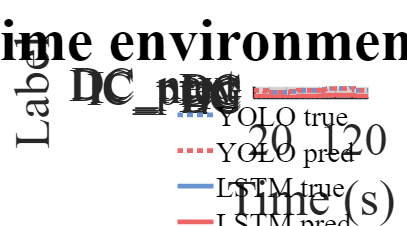

% 데이터 불러오기 (예제에서는 CSV 파일을 사용)
data = readtable('./output/EXO_on1_0815.csv', 'ReadVariableNames', false);

% 첫 번째 열: frame_idx, 두 번째 열: YOLO_pred, 네 번째 열: YOLO_true
frame_idx = (1:length(data.Var1))';
YOLO_pred = data.Var2;
YOLO_true = data.Var4;

a=4;
% 치환 함수 정의
replaceLabels = @(x) (6+a) * (x == 1) + (5+a) * (x == 0) + (4+a) * (x == 2) + (3+a) * (x == 6) + (2+a) * (x == 4) + (1+a) * (x == 3) + (a) * (x == 5);

% YOLO_true와 YOLO_pred 값 치환
YOLO_true = arrayfun(replaceLabels, YOLO_true);
YOLO_pred = arrayfun(replaceLabels, YOLO_pred);


% 축 레이블 설정
labels = {'IC', 'LG', 'DC','','IC\_prev', 'IC', 'IC\_next', 'LG', 'DC\_prev', 'DC', 'DC\_next'};
y_data = [0 1 2 3 0+a 1+a 2+a 3+a 4+a 5+a 6+a];

LSTM_pred=data.Var3;
LSTM_true=data.Var5;

% 치환 함수 정의
replaceLabels = @(x) 1 * (x == 2) + 0 * (x == 1) + 2 * (x == 0) ;

% YOLO_true와 YOLO_pred 값 치환
LSTM_true = arrayfun(replaceLabels, LSTM_true);
LSTM_pred = arrayfun(replaceLabels, LSTM_pred);

% 그래프 그리기

% 그래프 그리기
figure('Position', [100, 100, 1800, 1000]);  % 가로로 긴 그래프 설정
hold on;

plot(frame_idx, YOLO_true, Color=[104/255, 149/255, 210/255],LineWidth=4,LineStyle=":");
plot(frame_idx, YOLO_pred, Color=[238/255, 102/255, 102/255],LineWidth=4,LineStyle=":");


plot(frame_idx, LSTM_true, Color=[104/255, 149/255, 210/255],LineWidth=4);
plot(frame_idx, LSTM_pred, Color=[238/255, 102/255, 102/255],LineWidth=4);
% % 축 레이블 및 제목 설정
% ylabel('Label');
% title('Real-time Classification: YOLO','FontSize',30,'FontWeight','bold');
% % 범례 설정 (박스 없애기, 위치 설정)
% legend('YOLO true', 'YOLO pred', 'Box', 'off', 'FontSize', 20);
% % x 축 레이블 설정
% % y 축 설정 (라벨로 설정)
% set(gca, 'YTick', y_data, 'YTickLabel', labels_YOLO,'FontSize',18);
% 
% 
% xlim([frame_idx(1,:) frame_idx(end)]);
% % y축 범위 설정
% 
% grid on

% 축 레이블 및 제목 설정
set(gca, 'YTick', y_data, 'YTickLabel',labels,'FontSize',38,'FontName','Times New Roman');
ylabel('Label');
xlabel('Time (s)');
title('Real-time environment classification','FontSize',50,'FontWeight','bold','FontName','Times New Roman');
% 범례 설정 (박스 없애기, 위치 설정)
legend('YOLO true','YOLO pred', 'LSTM true', 'LSTM pred', 'Box', 'off', 'FontSize', 24,'FontName','Times New Roman');
% x 축 레이블 설정
% y 축 설정 (라벨로 설정)


xlim([frame_idx(1,:) frame_idx(end)]);
% y축 범위 설정
ylim([-1 11]);
grid on
% 그리기 종료
hold off;